function main
    % Initialize parameters
    pars = default_pars_STDP();
    
    % Parameters for STDP plot
    A_plus = pars.A_plus;
    A_minus = pars.A_minus;
    tau_stdp = pars.tau_stdp;
    time_diff = linspace(-5 * tau_stdp, 5 * tau_stdp, 50);
    dW = Delta_W(A_plus, A_minus, tau_stdp, time_diff);
    mySTDP_plot(A_plus, A_minus, tau_stdp, time_diff, dW);

    % Poisson spike train and LTP ratio generation
    pars = default_pars_STDP('T', 200, 'dt', 1);
    pre_spike_train_ex = Poisson_generator(pars, 10, 5, 2020);
    P = generate_P(pars, pre_spike_train_ex);
    my_example_P(pre_spike_train_ex, pars, P);

    % Simulate conductance-based LIF neuron with STDP
    pars = default_pars_STDP('T', 200, 'dt', 1);
    pars.gE_bar = 0.024;
    pars.gE_init = 0.024;
    pars.VE = 0;
    pars.tau_syn_E = 5;

    pre_spike_train_ex = Poisson_generator(pars, 10, 300, 2020);
    [v, rec_spikes, gE, P, M, gE_bar_update] = run_LIF_cond_STDP(pars, pre_spike_train_ex);

    % Plot results
    plot_results(pars, v, rec_spikes, gE, P, M, gE_bar_update, pre_spike_train_ex);
end

function pars = default_pars_STDP(varargin)
    % Set default parameters
    pars.V_th = -55;    
    pars.V_reset = -75; 
    pars.tau_m = 10;    
    pars.V_init = -65;  
    pars.V_L = -75;     
    pars.tref = 2;      
    pars.A_plus = 0.008;  
    pars.A_minus = 0.008 * 1.1;
    pars.tau_stdp = 20;   
    pars.T = 400;
    pars.dt = 0.1;
    
    % Override parameters
    for i = 1:2:length(varargin)
        pars.(varargin{i}) = varargin{i+1};
    end
    pars.range_t = 0:pars.dt:(pars.T-pars.dt);
end

function poisson_train = Poisson_generator(pars, rate, n, myseed)
    % Generate Poisson spike trains
    rng(myseed);
    Lt = length(pars.range_t);
    u_rand = rand(n, Lt);
    poisson_train = double(u_rand < rate * (pars.dt / 1000));
end

function dW = Delta_W(A_plus, A_minus, tau_stdp, time_diff)
    % Calculate STDP weight changes
    dW = zeros(size(time_diff));
    dW(time_diff <= 0) = A_plus * exp(time_diff(time_diff <= 0) / tau_stdp);
    dW(time_diff > 0) = -A_minus * exp(-time_diff(time_diff > 0) / tau_stdp);
end

function mySTDP_plot(A_plus, A_minus, tau_stdp, time_diff, dW)
    % Plot STDP curve
    figure;
    hold on;
    plot(time_diff, dW, 'k');
    plot([-5 * tau_stdp, 5 * tau_stdp], [0, 0], 'k--');
    plot([0, 0], [-A_minus, A_plus], 'k--');
    xlabel('t_{pre} - t_{post} (ms)');
    ylabel('\DeltaW');
    title('Biphasic STDP');
    hold off;
end

function P = generate_P(pars, pre_spike_train_ex)
    % Generate LTP ratio
    Lt = length(pars.range_t);
    n = size(pre_spike_train_ex, 1);
    P = zeros(n, Lt);
    for t = 1:Lt-1
        dP = -(pars.dt / pars.tau_stdp) * P(:, t) + pars.A_plus * pre_spike_train_ex(:, t+1);
        P(:, t+1) = P(:, t) + dP;
    end
end

function my_example_P(pre_spike_train_ex, pars, P)
    % Plot spike trains and LTP ratios
    figure;
    subplot(2, 1, 1);
    hold on;
    for i = 1:size(pre_spike_train_ex, 1)
        spike_times = pars.range_t(pre_spike_train_ex(i, :) > 0.5);
        plot(spike_times, i * ones(size(spike_times)), '|', 'MarkerSize', 10);
    end
    xlabel('Time (ms)');
    ylabel('Neuron ID');
    hold off;

    subplot(2, 1, 2);
    hold on;
    for i = 1:size(P, 1)
        plot(pars.range_t, P(i, :));
    end
    xlabel('Time (ms)');
    ylabel('P(t)');
    hold off;
end

function [v, rec_spikes, gE, P, M, gE_bar_update] = run_LIF_cond_STDP(pars, pre_spike_train_ex)
    % Simulate conductance-based LIF neuron
    Lt = length(pars.range_t);
    v = zeros(1, Lt);
    v(1) = pars.V_init;
    M = zeros(1, Lt);
    gE = zeros(1, Lt);
    gE_bar_update = pars.gE_init * ones(size(pre_spike_train_ex));
    rec_spikes = [];
    tr = 0;
    P = generate_P(pars, pre_spike_train_ex);
    
    for t = 1:Lt-1
        if tr > 0
            v(t) = pars.V_reset;
            tr = tr - 1;
        elseif v(t) >= pars.V_th
            rec_spikes = [rec_spikes, t * pars.dt];
            v(t) = pars.V_reset;
            M(t) = M(t) - pars.A_minus;
            gE_bar_update(:, t) = gE_bar_update(:, t) + P(:, t) * pars.gE_bar;
            gE_bar_update(gE_bar_update(:, t) > pars.gE_bar, t) = pars.gE_bar;
            tr = pars.tref / pars.dt;
        end
        
        % Update conductance and membrane potential
        gE(t+1) = gE(t) - (pars.dt / pars.tau_syn_E) * gE(t) + ...
                  sum(gE_bar_update(:, t) .* pre_spike_train_ex(:, t));
        v(t+1) = v(t) + pars.dt * (-(v(t) - pars.V_L) - gE(t+1) * (v(t) - pars.VE)) / pars.tau_m;
    end
end

function plot_results(pars, v, rec_spikes, gE, P, M, gE_bar_update, pre_spike_train_ex)
    % Plot simulation results
    figure;
    subplot(3, 2, 1);
    plot(pars.range_t, v);
    xlabel('Time (ms)');
    ylabel('V (mV)');

    subplot(3, 2, 2);
    hold on;
    for i = 1:10
        spike_times = pars.range_t(pre_spike_train_ex(i, :) > 0.5);
        plot(spike_times, i * ones(size(spike_times)), '|', 'MarkerSize', 10);
    end
    xlabel('Time (ms)');
    ylabel('Neuron ID');
    hold off;

    subplot(3, 2, 3);
    plot(pars.range_t, M);
    xlabel('Time (ms)');
    ylabel('M');

    subplot(3, 2, 4);
    hold on;
    for i = 1:10
        plot(pars.range_t, P(i, :));
    end
    xlabel('Time (ms)');
    ylabel('P');
    hold off;

    subplot(3, 2, 5);
    hold on;
    for i = 1:10
        plot(pars.range_t, gE_bar_update(i, :));
    end
    xlabel('Time (ms)');
    ylabel('gE_bar');
    hold off;

    subplot(3, 2, 6);
    plot(pars.range_t, gE);
    xlabel('Time (ms)');
    ylabel('gE');
end

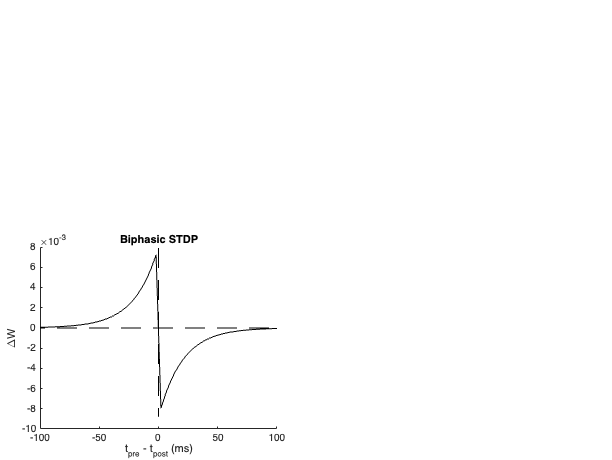

% Initialize parameters
pars = default_pars_STDP();

% Generate the STDP plot
A_plus = pars.A_plus;
A_minus = pars.A_minus;
tau_stdp = pars.tau_stdp;
time_diff = linspace(-5 * tau_stdp, 5 * tau_stdp, 50);

dW = Delta_W(A_plus, A_minus, tau_stdp, time_diff);
mySTDP_plot(A_plus, A_minus, tau_stdp, time_diff, dW);

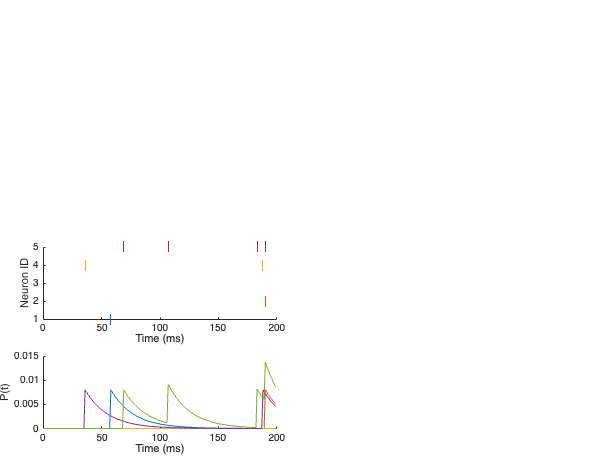


% Example with Poisson spike train and LTP ratio
pars = default_pars_STDP('T', 200, 'dt', 1);
pre_spike_train_ex = Poisson_generator(pars, 10, 5, 2020);
P = generate_P(pars, pre_spike_train_ex);
my_example_P(pre_spike_train_ex, pars, P);

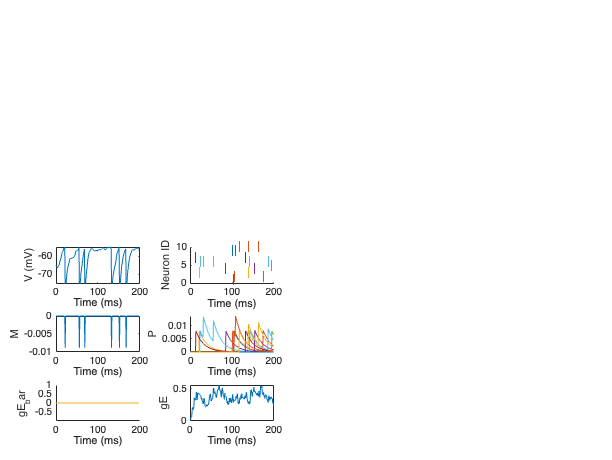


% Simulate conductance-based LIF neuron with STDP
pars = default_pars_STDP('T', 200, 'dt', 1);
pars.gE_bar = 0.024;
pars.gE_init = 0.024;
pars.VE = 0;
pars.tau_syn_E = 5;

pre_spike_train_ex = Poisson_generator(pars, 10, 300, 2020);
[v, rec_spikes, gE, P, M, gE_bar_update] = run_LIF_cond_STDP(pars, pre_spike_train_ex);

% Plot simulation results
plot_results(pars, v, rec_spikes, gE, P, M, gE_bar_update, pre_spike_train_ex);